**Below we recover the mean-field dynamics of particles interacting under logarithmic attraction, related to the Keller-Segel model for chemotaxis.**

## Load particle data

addpath(genpath('../'))
set(0,'DefaultFigurePosition',[1200 800 580 406])
clear all
close all
clc

select_example = 2;
examples = {'extrinsic_noise','constant_intrinsic_noise'};

if isequal(examples{select_example},'extrinsic_noise')
    load('datasets/log2D_N4000_nu0.mat'); 
    extrinsic_nz=10^(-1);
elseif isequal(examples{select_example},'constant_intrinsic_noise')
    load('datasets/log2D_N4000.mat'); extrinsic_nz = 0;
end

## Compute approximate particle distribution (Xscell, t)

%%% choose experiments from Xscell to use in regression 
exps = 1:8;

%%% choose number of particles to use from each experiment
NN = size(Xscell{1},1);

%%% choose histogram grid resolution
numx = 128 + 1;
numsdv = 3;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
scoord = 1;

%%% set extrinsic noise level
Xsnz = [extrinsic_nz 1];

%%% compute histogram
get_particle_distrib;

ET_load_data = 0.4488 


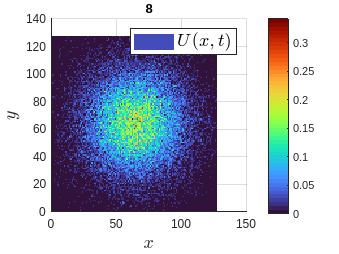

plotgap=8;
plot_distrib;

## Choose model library

%%% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

%%% local non-autonomous operators
driftpolys=[0:5]; drifttrigs=[];
diffpolys=[]; difftrigs=[0:2]; crossdrift=1;

%%% non-local operators
dim = size(Xscell{1},2)+1;
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:5],'Sing',[-1:0.5:0],'Exp',[],'Singeps',[0.001],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 1.3200 


## Set discretization

phi_class = {1,1};
sm_x = 5;
sm_t = 5;

%%% manually set test function params
p_x = 5; mxs = 25;
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 8;
tau_t = []; k_t = []; tauhat_t = [];

% %%% set test fcn params using cornerpoint
p_x = 7;tauhat_x = 1;
tau_x = [];k_x = [];mxs = 1;
p_t = 3;tauhat_t = 1;
tau_t = [];k_t = [];mts = 1;

%%% rescale coordinates and/or use approx. variance for improved conditioning
scales = 2;
covtol = 0;

%%% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-inf;

set_discretization;

ET_setdisc = 1.0541 


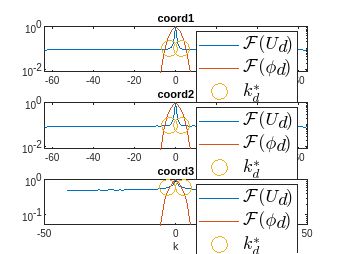


toggle_plot_fft = 1;
plot_Ufft;

## Build linear systems

build_Gb;

ET_build_Gb = 6.7513 


## Solve linear system

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags={'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 1.6371 


## get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = 0.0373824([x.^0.*y.^0.*t.^0]u^1)_{lap} + 0.152441convsing-1
Relative Res: ||b-G*W||_2/||b||_2 = 2.53e-01
Max Weight Error: max|W-W_{true}| = 4.22e-02
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 27 12 
[s_x s_t] = 5 2 
[p_x p_t] = 7 3 
 scales = 1.00e+00 2.96e+00 2.96e+00 8.33e-01 
      
Total particles = 32000 
Size of dataset = 128 128 81 
Size G = 6525 68 
Cond G = 7.11e+06
[lambda_hat gamma] = 1.048e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 7 
 
ET_load_data = 0.4488 
ET_build_lib = 1.3200 
ET_setdisc = 1.0541 
ET_build_Gb = 6.7513 
ET_solve_sparse_reg = 1.6371 
Elapsed time WSINDy = 11.2113 


## Display loss

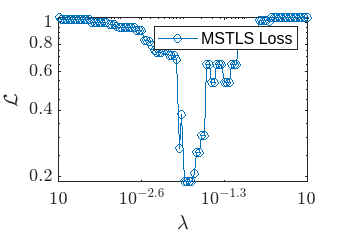

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

toggle_plot_drift = 0;
plot_driftdiff;

## Display interaction force

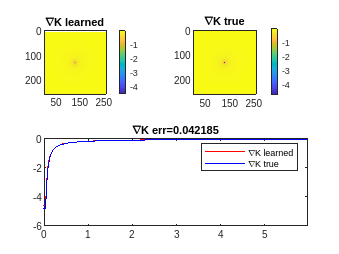

toggle_plot_IPforce = 1;
plot_K